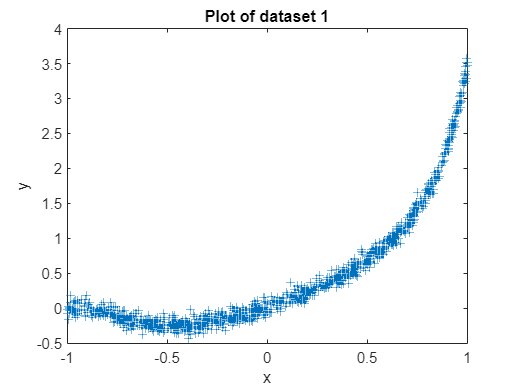

load dataset_1.mat

plot(x,y,"+") % initial plot of all the data
xlabel('x')
ylabel('y')
title('Plot of dataset 1')

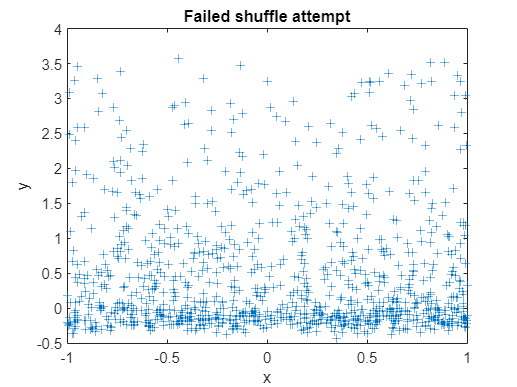

% Shuffling data to ensure fair split
x_shuffled = x(randperm(length(x))); % initial attempt but this didn't work
y_shuffled = y(randperm(length(y)));
plot(x_shuffled, y_shuffled, "+")
xlabel('x')
ylabel('y')
title('Failed shuffle attempt')

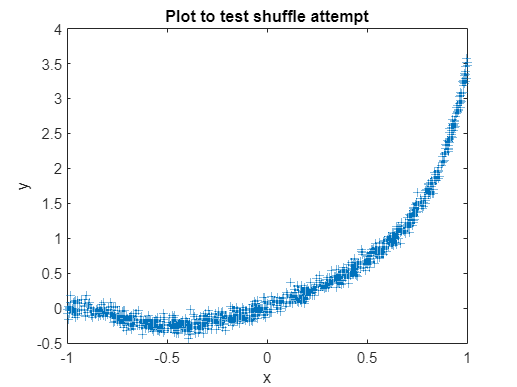


% Putting x and y into a vector and then scrambling
dataset1 = [x y];
shuffleIndices = randperm(length(dataset1));
dataset1(shuffleIndices,:);

plot(dataset1(:,1), dataset1(:,2), "+")
xlabel('x')
ylabel('y')
title('Plot to test shuffle attempt')

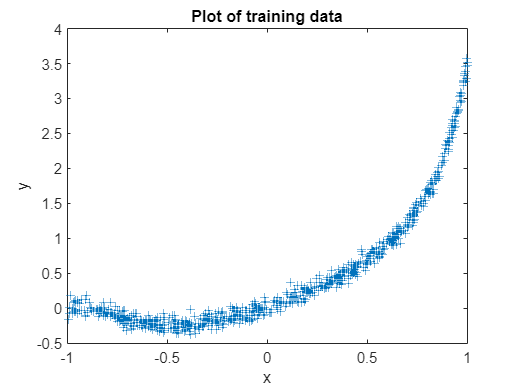

% Splitting data into 70% train and 30% test
splitPercent = 0.7;
trainSplit = floor(length(dataset1)*splitPercent);

dataset1_train = dataset1(1:trainSplit,:);
dataset1_test = dataset1(trainSplit+1:length(dataset1),:);

plot(dataset1_train(:,1), dataset1_train(:,2), "+")
xlabel('x')
ylabel('y')
title("Plot of training data")

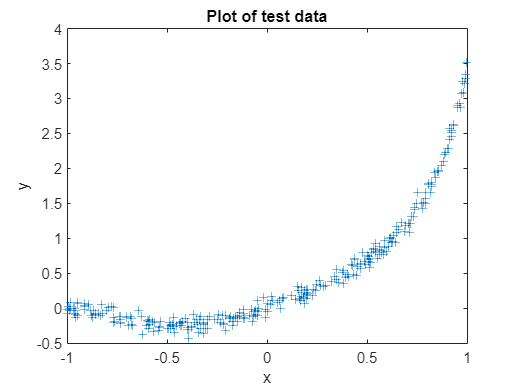


plot(dataset1_test(:,1), dataset1_test(:,2), "+")
xlabel('x')
ylabel('y')
title("Plot of test data")

# Look into the affect of sorting the data beforehand after the scramble

% Taking data back into individual arrays
XTrain = dataset1_train(:,1);
YTrain = dataset1_train(:,2);

XTest = dataset1_test(:,1);
YTest = dataset1_test(:,2);

degrees = 9 % = (number of coefficients)-1

degrees = 9


% Calculating coefficients
coef_l0 = fminsearch( @(A) l0_norm(A,XTrain,YTrain),rand(degrees,1));
coef_l1 = fminsearch( @(A) l1_norm(A,XTrain,YTrain),rand(degrees,1));
coef_l2 = fminsearch( @(A) l2_norm(A,XTrain,YTrain),rand(degrees,1));

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.004865 




% Evaluating polynomials using coefficients
yhat_l0_train = polyval(coef_l0,XTrain);
yhat_l1_train = polyval(coef_l1,XTrain);
yhat_l2_train = polyval(coef_l2,XTrain);

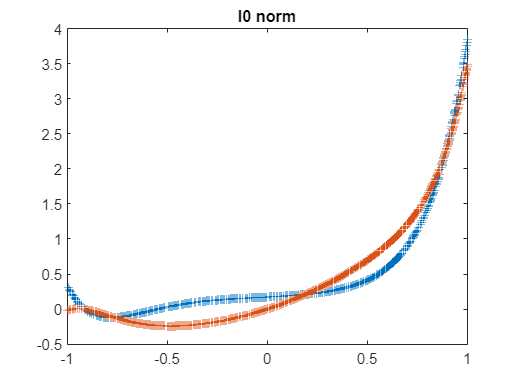

y_fit = polyval(coeffs,x);

% figure
% tiledlayout(1,3)
% nexttile
% plot(XTrain,yhat_l0_train,'+')
% hold on
% plot(x,y_fit,'+')
% title('l0 norm')
% hold off
% 
% nexttile
% plot(XTrain,yhat_l1_train,'+')
% hold on
% plot(x,y_fit,'+')
% title('l1 norm')
% hold off
% 
% nexttile
% plot(XTrain,yhat_l2_train,'+')
% hold on
% plot(x,y_fit,'+')
% title('l2 norm')
% hold off

figure
plot(XTrain,yhat_l0_train,'+')
hold on
plot(x,y_fit,'+')
title('l0 norm')
hold off

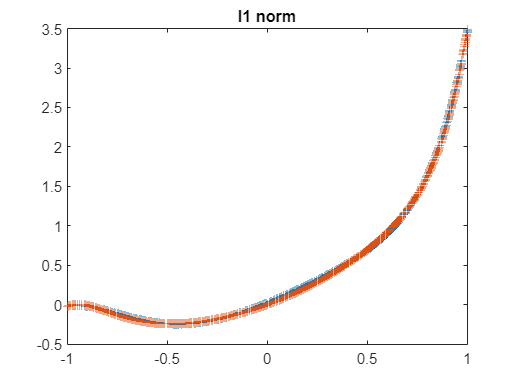


plot(XTrain,yhat_l1_train,'+')
hold on
plot(x,y_fit,'+')
title('l1 norm')
hold off

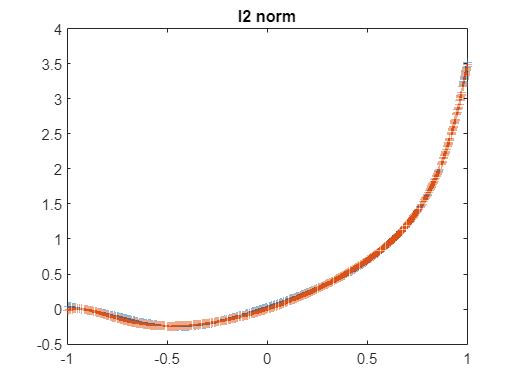


plot(XTrain,yhat_l2_train,'+')
hold on
plot(x,y_fit,'+')
title('l2 norm')
hold off

function y = l0_norm(A,x,y) % 10 norm function
    yhat = polyval(A,x);
    y = max(abs(yhat-y));
end

function y = l1_norm(A,x,y) % l1 norm function
    yhat = polyval(A,x);
    y = mean(abs(yhat-y));
end

function y = l2_norm(A,x,y) % l2 norm  function
    yhat = polyval(A,x);
    y = mean(abs(yhat-y).^2);
end

function y = coeffPlot(XTrain,yhat,x,y,coeffs,title)
    plot(XTrain,yhat,'+')
    hold on
    plot(x,polyval(coeffs,x),'+')
    xlabel('x')
    ylabel("yhat")
    title(title)
    hold off
end